
A=0:255

A =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


step=256/4

step = 64

QA1=quant(A,step)

QA1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    64    64    64    64    64    64    64    64    64    64    64    64    64    64    64    64    64    64


partition = step:step:256-step

partition =     64   128   192


codebook = step/2:step:256-step/2

codebook =     32    96   160   224


[indx,QA2] = quantiz(A, partition, codebook)  

indx =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


QA2 =     32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32    32


% A is the length of signal, 
% Partition contains the boundries and 
% codebook contains the output which must be placed in the boundries.

unique(QA1)

ans =      0    64   128   192   256


unique(QA2)

ans =     32    96   160   224


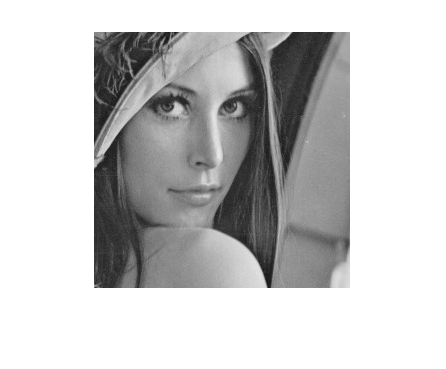

imshow("lena_face.png")

I=gpuArray(imread("lena_face.png"))

I = <page truncated: showing [1:32, 1:32] of 256-by-256>

  256×256 gpuArray uint8 matrix

  Columns 1 through 23

   138   140   134   139   135   137   131   138   135   131   110    86   132   132   139   133   128   103   100    93    83    79    63
   126   133   134   142   140   142   136   141   142   134   109    77   121   141   142   126   100   105    98    74    65    60    50
   135   138   132   134   133   138   141   151   147   132   112    86   116   142   129   110    86    80    70    61    62    55    52
   128   132   131   134   137   141   143   150   146   135   123    95   108   138   116    92    71    57    60    62    53    59    82
    87   106   124   132   137   136   142   151   139   133   119    84    85   117    95    66    66    64    62    55    57    83   106
   104    89    77    81   113   133   140   136   143   126   


% 128, 64, 32, 16, 8

%A=0:255


reshapedImage=reshape(I,256*256,1)

reshapedImage = <page truncated: showing [1:1000, 1:1] of 65536-by-1>

  65,536×1 gpuArray uint8 column vector

   138
   126
   135
   128
    87
   104
   117
   129
   113
   110
   100
   106
   105
   113
   119
    76
    60
    65
    81
    73
    72
    76
    60
    63
    49
    50
    42
    39
    48
    46
    37
    37
    39
    42
    47
    49
    64
    76
    63
    49
    36
    50
    49
    46
    60
    90
   108
    98
    55
    75
    74
    53
    40
    43
    47
    48
    59
    75
    83
    88
    99
   101
    98
   102
    98
    65
    56
    42
    34
    44
    41
    39
    49
    45
    39
    38
    42
    43
    44
    46
    37
    52
    49
    52
    46
    47
    63
    47
    56
    51
    49
    45
    48
    50
    47
    54
    48
    50
    48
    42
    47
    49
    38
    38
    35
    34
    26
    29
    4

imageSize=256

imageSize = 256

     4

     8



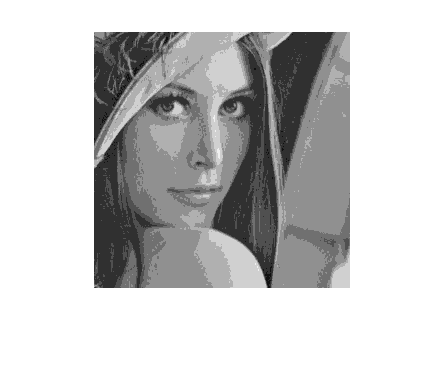

    16



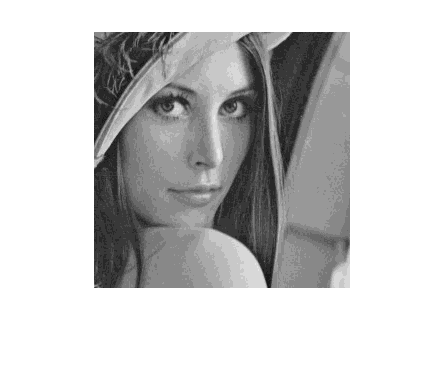

    32



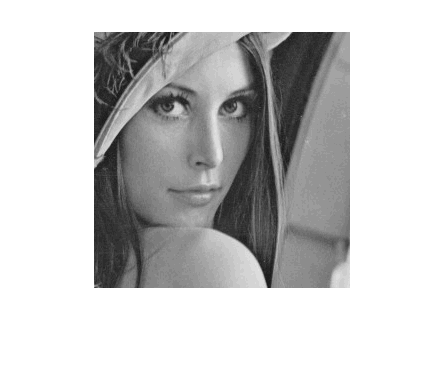

    64



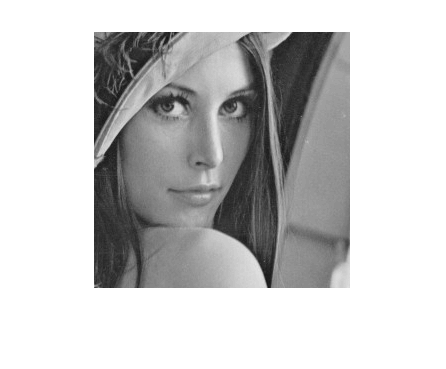

   128



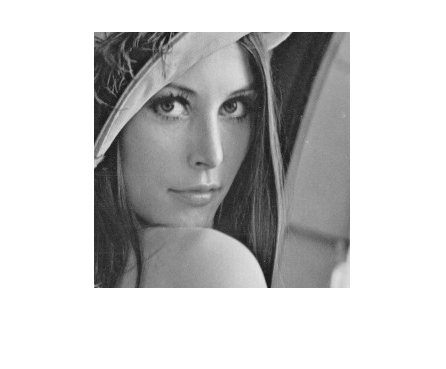


for i=2.^(2:7)
    disp(i)
    quantizationCalculation(i,reshapedImage,imageSize)
end


%Inoisy = reshapedImage + uint8(10*randn(256,256));

I2=gpuArray(imread("lena_face.png"))

I2 = <page truncated: showing [1:32, 1:32] of 256-by-256>

  256×256 gpuArray uint8 matrix

  Columns 1 through 23

   138   140   134   139   135   137   131   138   135   131   110    86   132   132   139   133   128   103   100    93    83    79    63
   126   133   134   142   140   142   136   141   142   134   109    77   121   141   142   126   100   105    98    74    65    60    50
   135   138   132   134   133   138   141   151   147   132   112    86   116   142   129   110    86    80    70    61    62    55    52
   128   132   131   134   137   141   143   150   146   135   123    95   108   138   116    92    71    57    60    62    53    59    82
    87   106   124   132   137   136   142   151   139   133   119    84    85   117    95    66    66    64    62    55    57    83   106
   104    89    77    81   113   133   140   136   143   126  

reshapedImage1=reshape(I2+ uint8(10*randn(256,256)),256*256,1);
reshapedImageNoise = reshapedImage1;


disp("16 with Noise")

16 with Noise


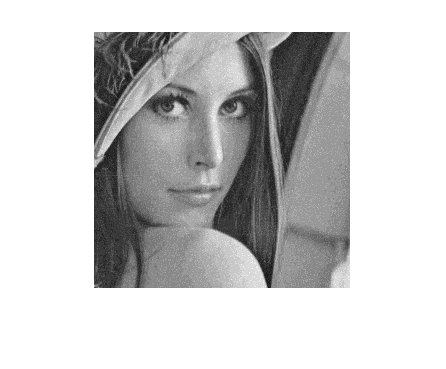

quantizationCalculation(16,reshapedImageNoise,imageSize);

disp("16 without Noise")

16 without Noise


quantizationCalculation(16,reshapedImage,imageSize);

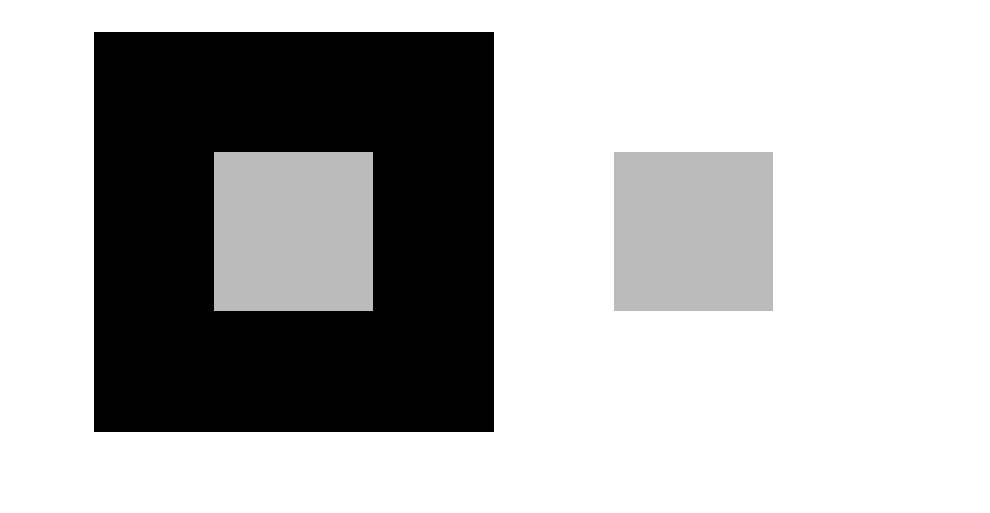

innerBoxColour=180;  %180
Bg1=63;
Bg2=223;
im1=ones(400)*innerBoxColour;
im1(1:120,:)=Bg1;
im1(280:400,:)=Bg1;
im1(120:280,1:120)=Bg1;
im1(120:280,280:400)=Bg1;
im1=uint8(im1);

im2=ones(400)*innerBoxColour;
im2(1:120,:)=Bg2;
im2(280:400,:)=Bg2;
im2(120:280,1:120)=Bg2;
im2(120:280,280:400)=Bg2;
im2=uint8(im2);

showTogether=[im1,im2];
imshow(showTogether,[])

function quantizationCalculation(levels,reshapedImage,imageSize) 
step=imageSize/levels;
QA1=quant(reshapedImage,step);
partition = step:step:imageSize-step;
codebook = step/2:step:imageSize-step/2;
[indx,QA2] = quantiz(reshapedImage, partition, codebook);

reshapedImageAgain=reshape(QA2,256,256);
QA2=uint8(reshapedImageAgain);
figure(levels);
imshow(QA2);
end